- 几何

[`gm`](https://ww2.mathworks.cn/help/pde/ug/multicuboid.html#bvj_ihm-gm) `= multicuboid(`[`W`](https://ww2.mathworks.cn/help/pde/ug/multicuboid.html#bvj_ihm-W)`,`[`D`](https://ww2.mathworks.cn/help/pde/ug/multicuboid.html#bvj_ihm-D)`,`[`H`](https://ww2.mathworks.cn/help/pde/ug/multicuboid.html#bvj_ihm-H)`)` 通过组合多个立方单元创建几何。

创建每个长方体时，请`multicuboid`使用以下坐标系。

gm = multicuboid(2 ,3 ,5)

gm =   DiscreteGeometry - 属性:

       NumCells: 1
       NumFaces: 6
       NumEdges: 12
    NumVertices: 8


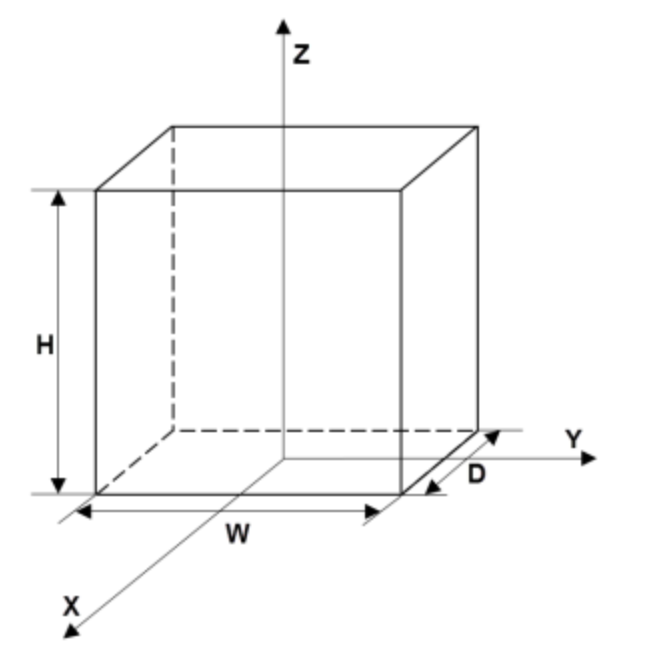

例如：

gm1 = multicuboid([2 3 5],[4 6 10],3)

gm1 =   DiscreteGeometry - 属性:

       NumCells: 3
       NumFaces: 18
       NumEdges: 36
    NumVertices: 24


- 嵌套相同高度的长方体

model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm1

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


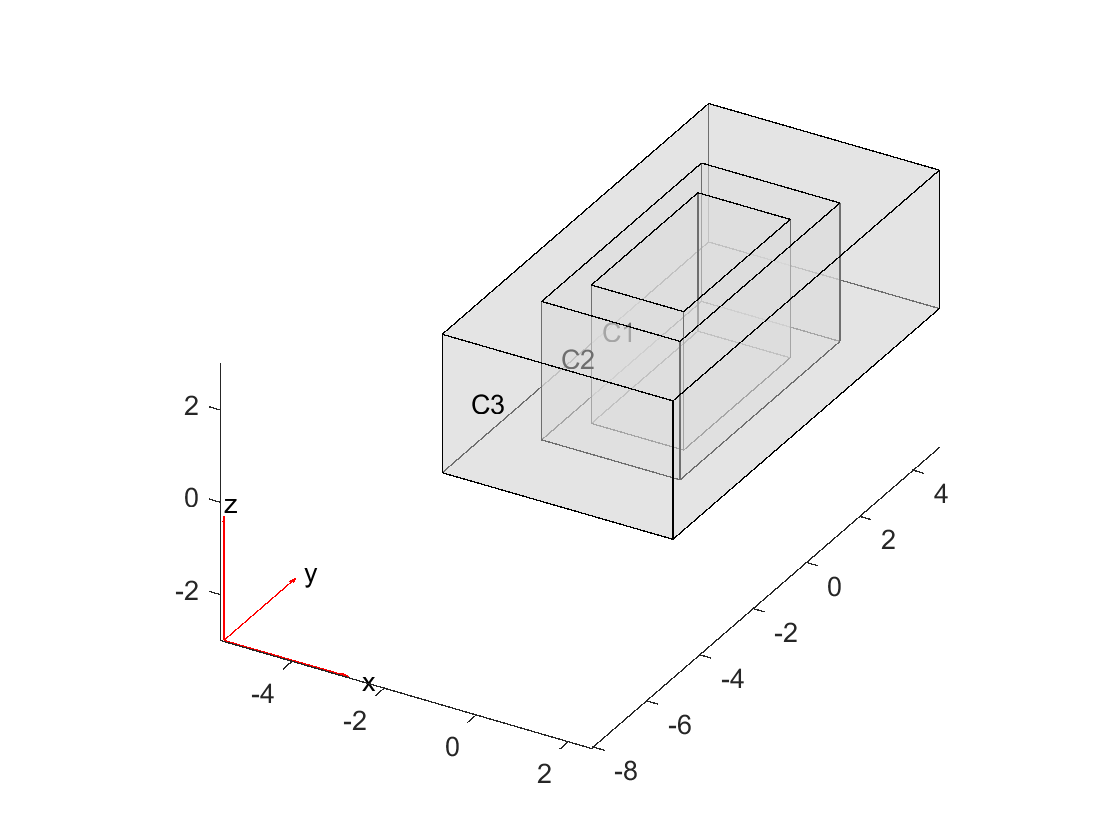

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

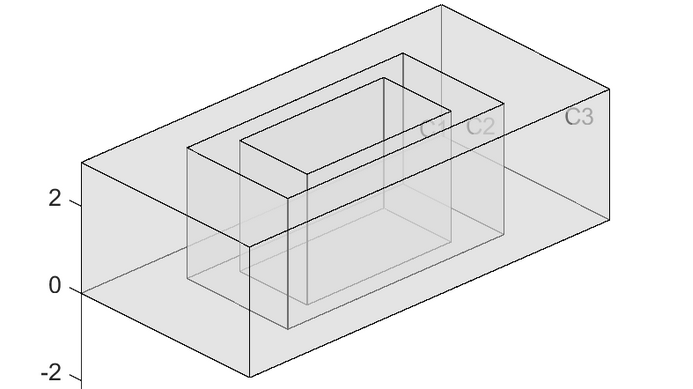

    2.堆叠长方体

 创建由四个堆叠的长方体组成的几何，并将此几何包含在PDE模型中。

通过将`multicuboid`函数与`ZOffset`参数一起使用来创建几何。生成的几何图形由彼此堆叠的四个单元组成。其中Z0ffset的作用就是给定Z方向的偏移量。最开始地面在z=0,第二个在0+1处，第三个在0+1+2处......

gm = multicuboid(5,10,[1 2 3 4],'ZOffset',[0 1 3 6])

gm =   DiscreteGeometry - 属性:

       NumCells: 4
       NumFaces: 21
       NumEdges: 36
    NumVertices: 20


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


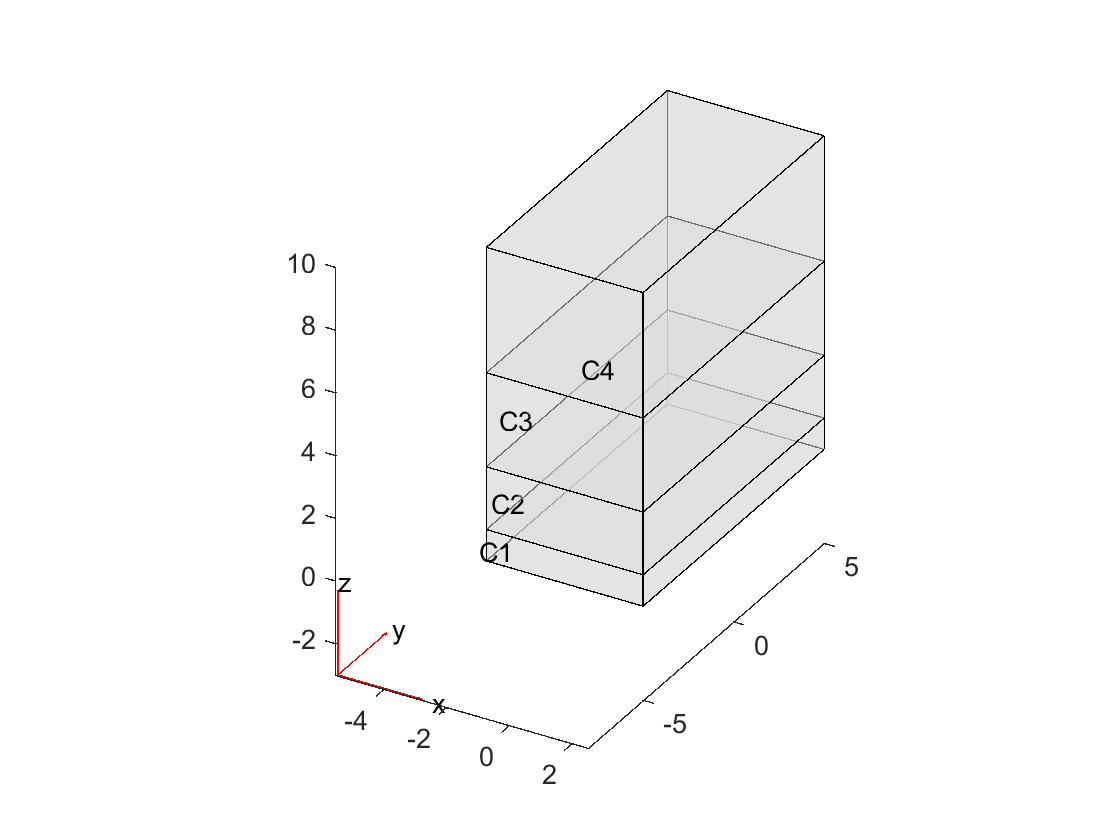

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

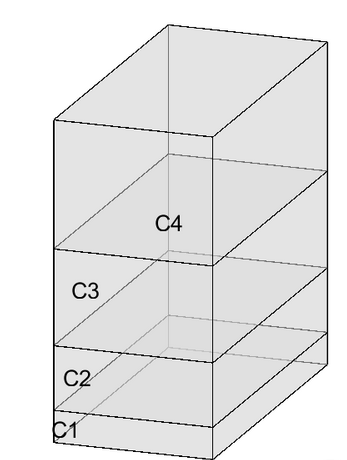

    3.单个长方体 

创建由单个长方体组成的几何并将此几何包含在PDE模型中。

使用该`multicuboid`函数创建单个长方体。生成的几何图形由一个单元组成。

%%单个长方体
gm = multicuboid(5,10,7)

gm =   DiscreteGeometry - 属性:

       NumCells: 1
       NumFaces: 6
       NumEdges: 12
    NumVertices: 8


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


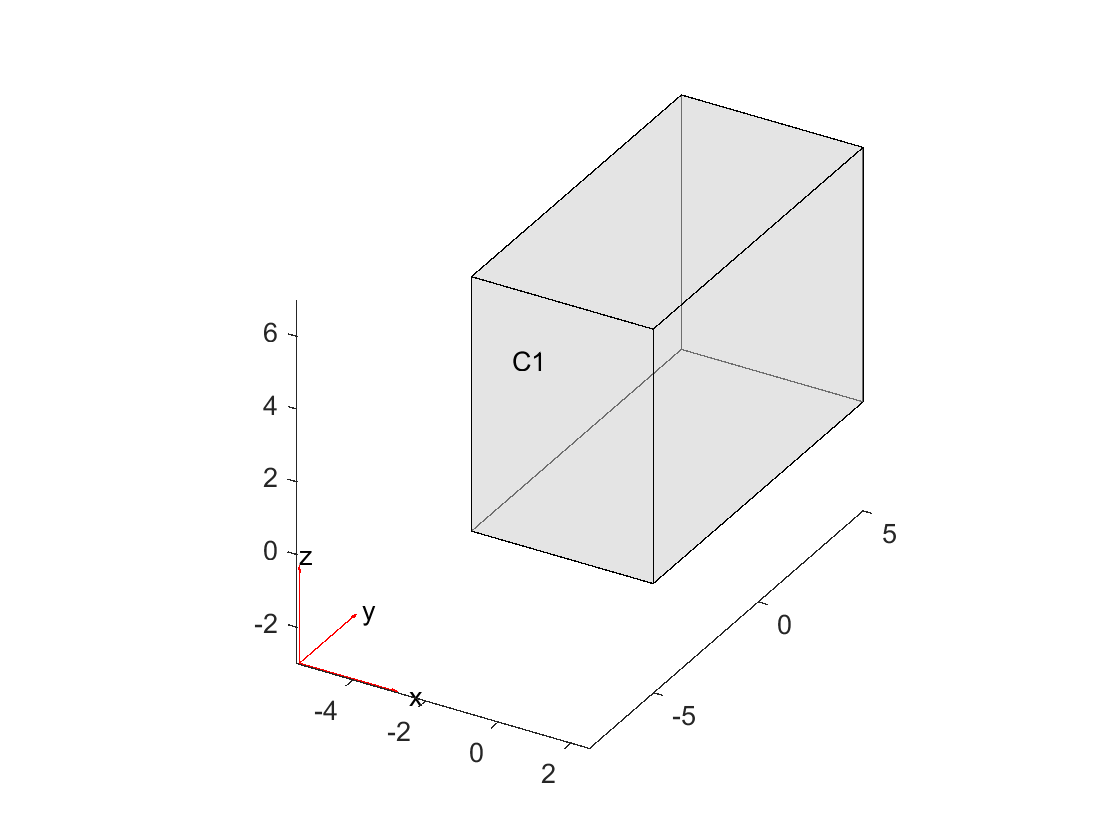

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

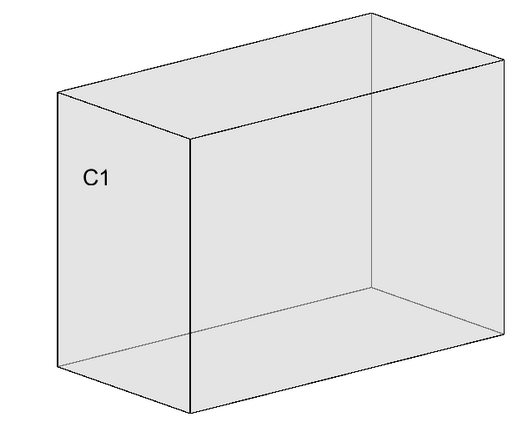

    4. 空心立方体

创建一个空心立方体，并将其作为几何体包含在PDE模型中。

通过将`multicuboid`函数与`Void`参数一起创建一个空心立方体。生成的几何图形由一个单元组成。

注意：True代表是空！第一元素即代表将第一个实体设置为空。

gm = multicuboid([6 10],[6 10],10,'Void',[true,false])

gm =   DiscreteGeometry - 属性:

       NumCells: 1
       NumFaces: 10
       NumEdges: 24
    NumVertices: 16


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


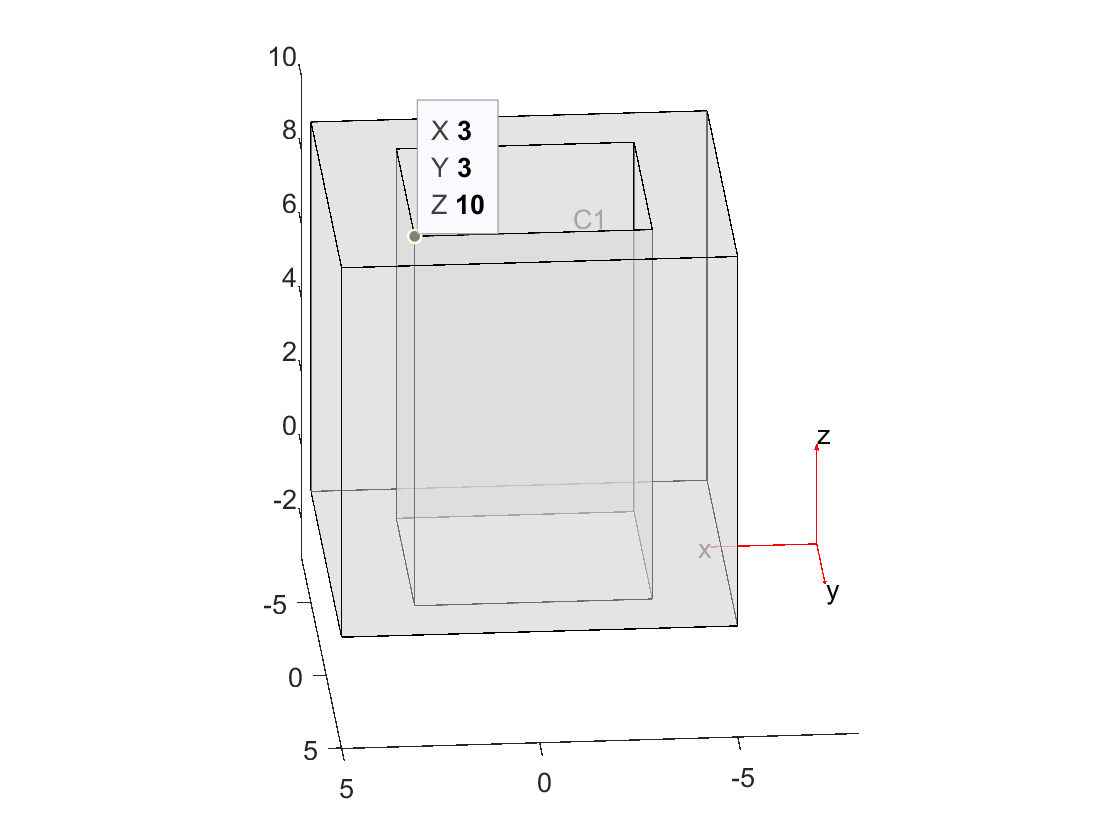

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)